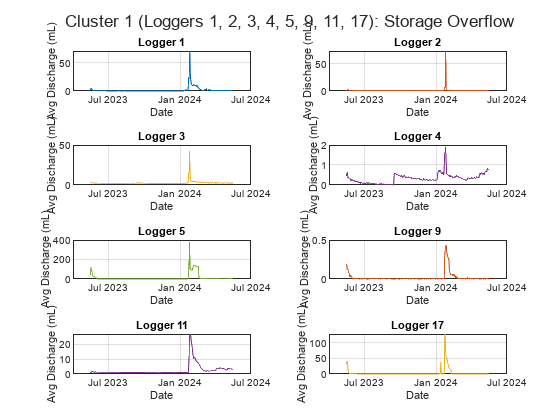

%Result_Clusters_Daily_Discharge_mL

% Clear workspace and command window
clear;
clc;

% Read data from the Excel file
drip_data = readtable('converted_COMBINATIONJANMAY2024_15toGuy.xlsx', 'VariableNamingRule', 'preserve');

% Extract dates, and drip count data
dates = drip_data{:, 1}; % Time is in column 1
drip_count = drip_data{:, 2:end}; % Drip count is in columns 2 to 21

% Check if d_dates is in numeric format (Excel serial date) or string
% If numeric, convert to datetime
if isnumeric(dates)
    dates = datetime(dates, 'ConvertFrom', 'excel');  % Convert from Excel date serial numbers
elseif ischar(dates) || isstring(dates)
    dates = datetime(dates, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');  % Adjust if your format is different
end

% Create a figure for 4 subplots
gcf = figure;

% Define a set of colors (20 unique colors)
colors = lines(20);  % Use MATLAB's 'lines' colormap, which generates distinct colors

% --- Subplot 1: Loggers 1, 2, 3, 4, 5, 9, 11, 17 ---
subplot(2, 2, 1);  % 2 rows, 2 columns, first subplot

% Create a tiled layout (2x4) for loggers 1, 2, 3, 4, 5, 9, 11, 17
tiledlayout(4, 2);

loggers_3 = [1, 2, 3, 4, 5, 9, 11, 17];
for i = 1:8
    nexttile;
    % Extract the data for the current logger
    logger_data = drip_count(:, loggers_3(i));

    % Group the data by day and calculate the daily averages
    [unique_days, ~, idx] = unique(dateshift(dates, 'start', 'day'));  % Get unique days
    daily_avg_drip_count(:, loggers_3(i)) = accumarray(idx, logger_data, [], @mean);  % Calculate daily average

    % Plot the daily average data for the logger
    plot(unique_days, daily_avg_drip_count(:, loggers_3(i)), 'Color', colors(loggers_3(i), :));  % Plot the data
    title(['Logger ' num2str(loggers_3(i))]);
    xlabel('Date');
    ylabel('Avg Discharge (mL)');
    grid on;
    %axis padded;
end
sgtitle('Cluster 1 (Loggers 1, 2, 3, 4, 5, 9, 11, 17): Storage Overflow'); % Title for Cluster 1

% Save the figure (uncomment to save)
saveas(gcf, 'Cluster_Matrix_Base Flow.png');  % Saves the current figure
exportgraphics(gcf, 'Cluster_Matrix_Base Flow2.png', 'Resolution', 1500);  % Save with 1500 DPI resolution

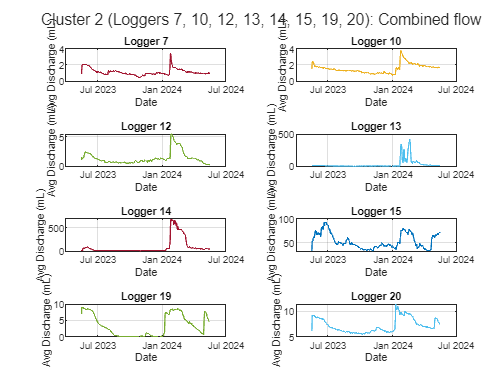



% --- Subplot 2: Loggers 7, 10, 12, 13, 14, 15, 19, 20 ---
subplot(2, 2, 2);  % 2 rows, 2 columns, second subplot

% Create a tiled layout (2x4) for loggers 7, 10, 12, 13, 14, 15, 19, 20
tiledlayout(4, 2);

loggers_2 = [7, 10, 12, 13, 14, 15, 19, 20];
for i = 1:8
    nexttile;
    % Extract the data for the current logger
    logger_data = drip_count(:, loggers_2(i));

    % Group the data by day and calculate the daily averages
    [unique_days, ~, idx] = unique(dateshift(dates, 'start', 'day'));  % Get unique days
    daily_avg_drip_count(:, loggers_2(i)) = accumarray(idx, logger_data, [], @mean);  % Calculate daily average

    % Plot the daily average data for the logger
    plot(unique_days, daily_avg_drip_count(:, loggers_2(i)), 'Color', colors(loggers_2(i), :));  % Plot the data
    title(['Logger ' num2str(loggers_2(i))]);
    xlabel('Date');
    ylabel('Avg Discharge (mL)');
    grid on;
    %axis padded;
end
sgtitle('Cluster 2 (Loggers 7, 10, 12, 13, 14, 15, 19, 20): Combined flow'); % Title for Cluster 2

% Save the figure (uncomment to save)
saveas(gcf, 'Cluster_Storage_OverFlow.png');  % Saves the current figure
exportgraphics(gcf, 'Cluster_Storage_OverFlow2.png', 'Resolution', 1500);  % Save with 1500 DPI resolution

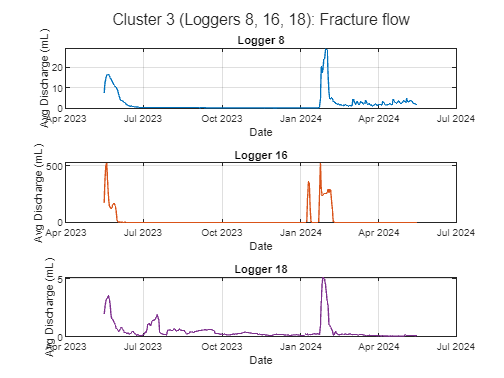


% --- Subplot 3: Loggers 8, 16, 18 ---
subplot(2, 2, 3);  % 2 rows, 2 columns, third subplot

% Create a tiled layout (1x3) for loggers 8, 16, and 18
tiledlayout(3, 1);

loggers_1 = [8, 16, 18];
for i = 1:3
    nexttile;
    % Extract the data for the current logger
    logger_data = drip_count(:, loggers_1(i));

    % Group the data by day and calculate the daily averages
    [unique_days, ~, idx] = unique(dateshift(dates, 'start', 'day'));  % Get unique days
    daily_avg_drip_count(:, loggers_1(i)) = accumarray(idx, logger_data, [], @mean);  % Calculate daily average

    % Plot the daily average data for the logger
    plot(unique_days, daily_avg_drip_count(:, loggers_1(i)), 'Color', colors(loggers_1(i), :));  % Plot the data
    title(['Logger ' num2str(loggers_1(i))]);
    xlabel('Date');
    ylabel('Avg Discharge (mL)');
    grid on;
    %axis padded;
end
sgtitle('Cluster 3 (Loggers 8, 16, 18): Fracture flow');  % Title for Cluster 3

% Save the figure (uncomment to save)
saveas(gcf, 'Cluster_Fracture_OverFlow.png');  % Saves the current figure
exportgraphics(gcf, 'Cluster_Fracture_OverFlow2.png', 'Resolution', 1500);  % Save with 1500 DPI resolution

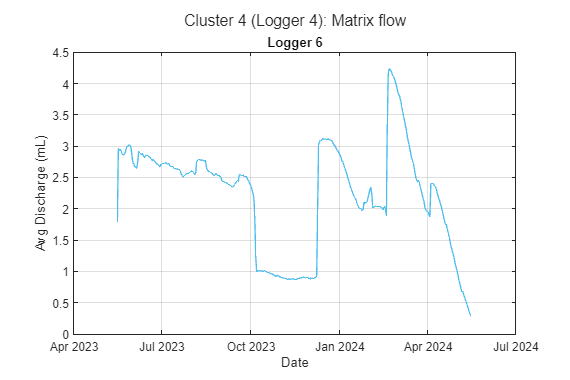


% --- Subplot 4: Logger 6 ---
subplot(2, 2, 4);  % 2 rows, 2 columns, fourth subplot
tiledlayout(1, 1);

% Extract the data for logger 6
logger_4 = 6;
logger_data = drip_count(:, logger_4);

% Group the data by day and calculate the daily averages
[unique_days, ~, idx] = unique(dateshift(dates, 'start', 'day'));  % Get unique days
daily_avg_drip_count(:, logger_4) = accumarray(idx, logger_data, [], @mean);  % Calculate daily average

% Plot the daily average data for logger 6
nexttile;
plot(unique_days, daily_avg_drip_count(:, logger_4), 'Color', colors(logger_4, :));  % Plot the data
title(['Logger ' num2str(logger_4)]);
xlabel('Date');
ylabel('Avg Discharge (mL)');
grid on;
%axis padded;
sgtitle('Cluster 4 (Logger 4): Matrix flow'); % Title for Cluster 4

% Adjust the layout to avoid overlap
tight_layout = get(gcf, 'Position');
set(gcf, 'Position', [tight_layout(1), tight_layout(2), 1200, 800]);


%Save the figure (uncomment to save)
saveas(gcf, 'Cluster_Mixed.png');  % Saves the current figure
exportgraphics(gcf, 'Cluster_Mixed2.png', 'Resolution', 1500);  % Save with 1500 DPI resolution